Мухин Георгий РЛ6-31 

**Условие задачи:**

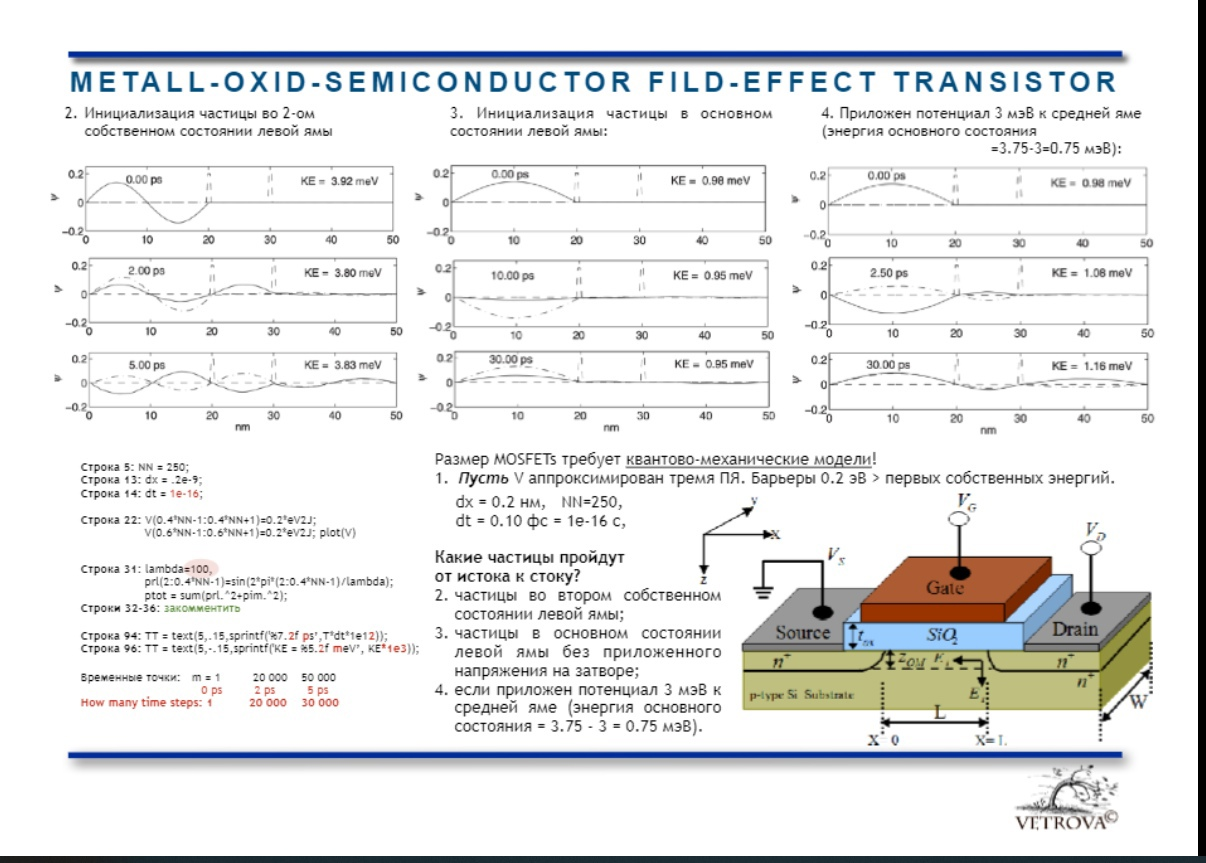

**Решение**

clear all, close all, clc % Se1_1.m. % This is a 1D FDTD simulation of psi.
disp(datetime('now'));

   17-Dec-2021 10:05:03



NN = 250;
Np = 250; % Number of points in the problem space.
hbar = 1.054e-34; % Plank's constant
m0 = 9.1e-31; % Free space mass of an electron
meff = 1.0; % Effective mass: Si is 1.08, Ge is 0.067, GaAs is 0.55
m = meff*m0; % Mass of an electron
eV2J = 1.6e-19; % Energy conversion factors
J2eV = 1/eV2J;
dx = 0.2e-9; % The cell size
dt = 1e-16; % Time steps 
ra = (0.5*hbar/m)*(dt/dx^2); % ra must be < .15
DX = dx*1e9; % Cell size in nm.
XX = (1:Np)*DX; % Length in nm for plotting
Dsquared=( diag(ones(1, Np - 1),1)-2*diag(ones(1,Np))+diag(ones(1,Np-1),-1) );

%Initialize a sine wave in a gaussian envelope
%sigma = 20; % Pulse width
lambda = 100;
[prl, pim, ptot] = set_state_function(NN, lambda);

pnorm =  7.07


pnorm = 7.07

pnorm = 7.0700

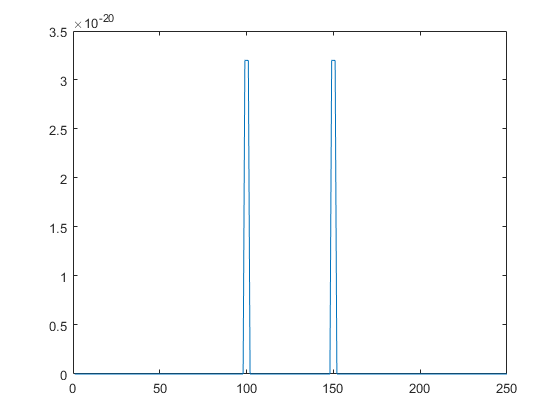

[V,nc_b1,nc_b2]=set_potential_gates(NN, eV2J);

normalization =  1.00
normalization =  1.00
normalization =  1.00


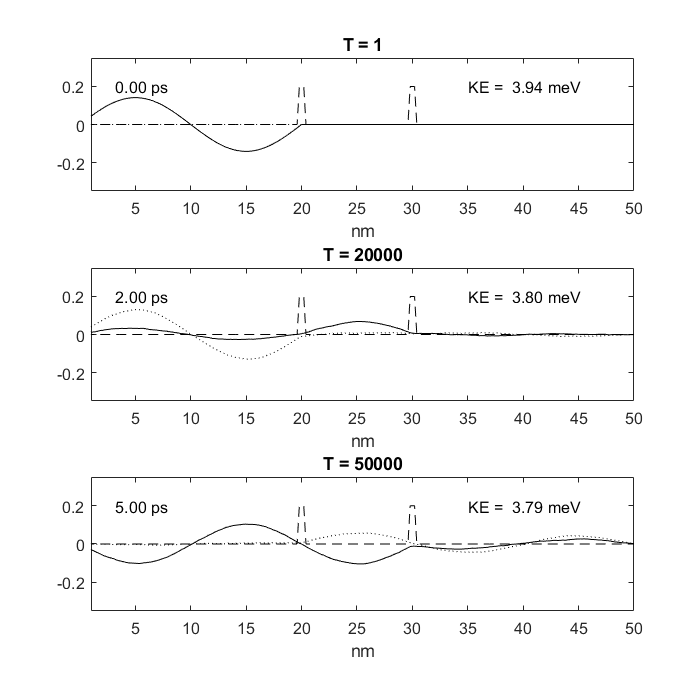

n_step = [1 19999 30000 0];
Main(n_step, DX, Np, XX, J2eV, m, ra, Dsquared, dt, dx, hbar, V, prl, pim, ptot);



figure;
lambda = 200;
[prl, pim, ptot] = set_state_function(NN, lambda);

pnorm =  7.07


pnorm = 7.07

pnorm = 7.0700

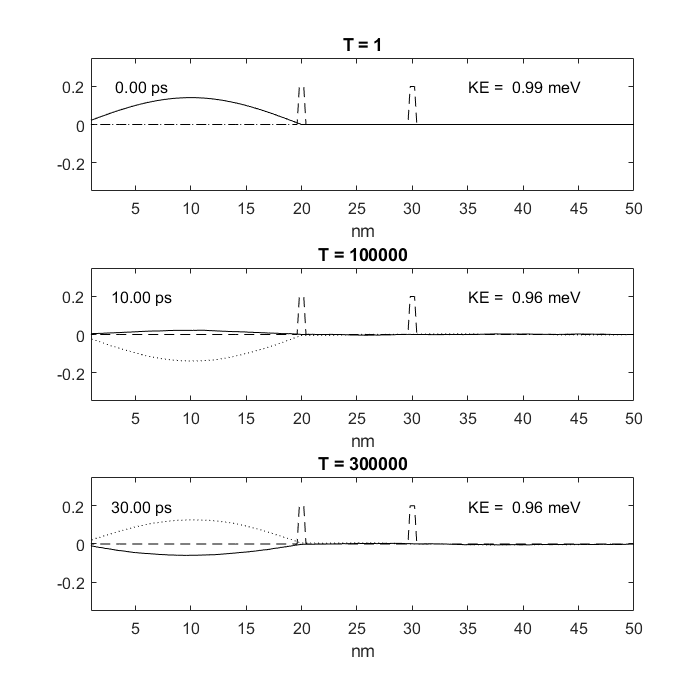

normalization =  1.00
normalization =  1.00
normalization =  1.00


n_step = [1 99999 200000 0];
Main(n_step, DX, Np, XX, J2eV, m, ra, Dsquared, dt, dx, hbar, V, prl, pim, ptot);

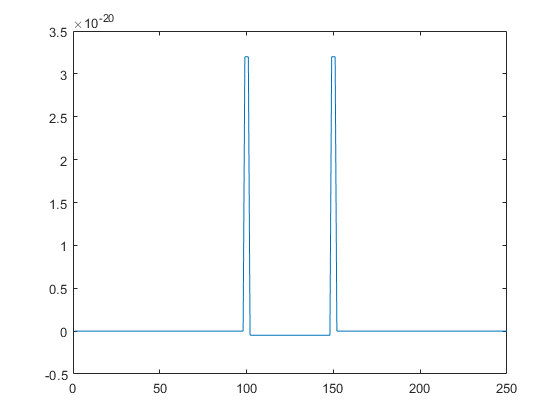


figure;
V(nc_b1 + 2 : nc_b2 - 2) = -0.003 * eV2J;
plot(V);

normalization =  1.00
normalization =  1.00
normalization =  1.00


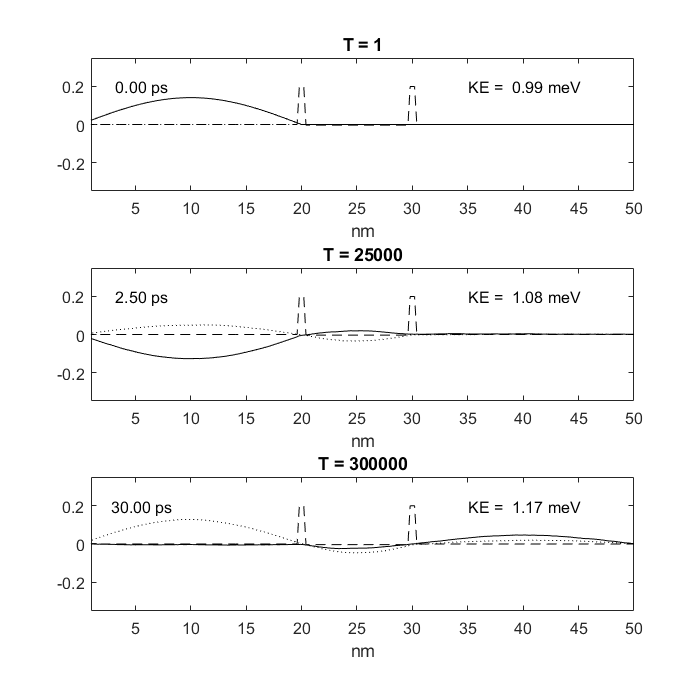


n_step = [1 24999 275000 0];
Main(n_step, DX, Np, XX, J2eV, m, ra, Dsquared, dt, dx, hbar, V, prl, pim, ptot);



figure;

function [prl, pim, ptot] = set_state_function(NN, lambda)
     prl(2 : 0.4 * NN) = sin(2 * pi * (2 : 0.4 * NN) / lambda);
     prl(0.4 * NN : NN) = 0;
     prl = prl';
     pim(1 : NN) = 0;
     pim = pim';
     ptot = prl + 1i * pim;
     pnorm = sqrt(sum(ptot.*conj(ptot))); % This should have the value 1
     fprintf('pnorm = %5.2f\n', pnorm);
     prl = prl / pnorm;
     pim = pim / pnorm;
     ptot = prl + 1i * pim;
end

function [T, prl, pim, ptot] = FDTD(T, n_step, Nstep, prl, ra, Dsquared, pim, dt, hbar, V)
     for mm = 1 : n_step(Nstep)
         T = T + 1;
         prl = prl - ra * Dsquared* pim + (dt / hbar) * V .* pim;
         pim = pim + ra * Dsquared* prl - (dt / hbar) * V .* prl;
     end
     ptot = prl + 1i * pim;
end

function [KE, PE] = CalcEnergy(J2eV, hbar, dx, m, ptot, Dsquared, V)
     KE = J2eV * real(- (hbar / dx) ^ 2 / (2 * m) * ptot' * (Dsquared * ptot)); 
     PE = J2eV * ptot' * (V .* ptot);
end

function MyPlot(Nstep, XX, prl, pim, J2eV, V, DX, Np, T, dt, KE, PE)
     subplot(3, 1, Nstep)
     plot(XX, prl, 'k') 
     hold on
     plot(XX, pim, ':k')
     plot(XX, J2eV * V, '--k')
     hold off
     axis([1 DX*Np -0.35 0.35])
     TT = text(2, 0.2, sprintf('%7.2f ps', T * dt * 1e12));
     set(TT, 'fontsize', 12)
     TT = text(35, 0.2, sprintf('KE = %5.2f meV', round(KE * 1e3 * 100) / 100));
     set(TT, 'fontsize', 12)
     xlabel('nm');
     title(sprintf('T = %d', T))
     set(gca, 'fontsize', 12)
     set(gcf,'position',[0, 0, 700, 700])
end

function Main(n_step, DX, Np, XX, J2eV, m, ra, Dsquared, dt, dx, hbar, V, prl, pim, ptot)
     T = 0;
     Nstep = 1;
     while n_step(Nstep) > 0
         [T, prl, pim, ptot] = FDTD(T, n_step, Nstep, prl, ra, Dsquared, pim, dt, hbar, V);
         [KE, PE] = CalcEnergy(J2eV, hbar, dx, m, ptot, Dsquared, V);
         fprintf('normalization = %5.2f\n', ptot' * ptot);
         MyPlot(Nstep, XX, prl, pim, J2eV, V, DX, Np, T, dt, KE, PE);
         Nstep = Nstep + 1;
     end
end

function [V,nc_b1,nc_b2]=set_potential_gates(NN, eV2J)
    V=zeros(1,NN)';
    nc_b1 = 2/5 * NN;
    nc_b2 = 3/5 * NN;
    V(nc_b1 - 1 : nc_b1 + 1) = 0.2 * eV2J;
    V(nc_b2 - 1 : nc_b2 + 1) = 0.2 * eV2J;
    plot(V);
end
